# WorkSheet 10

Problem 2:

% Define the function
f = @(t, y) -15*y;

% Parameters
tspan = [0, 10];
ic = 1;
nsteps = [10, 100, 1000, 10000]; % For varying nsteps

% Numerical solutions using backwardEuler and forwardEuler
% For backwardEuler, use the function defined above
% Implement forwardEuler similarly or refer to worksheet 5 as mentioned

% Analytical solution
t_analytic = linspace(tspan(1), tspan(2), 1000);
y_analytic = exp(-15*t_analytic);

% Plotting
figure;
hold on;
plot(t_analytic, y_analytic, 'LineWidth', 2); % Analytical solution
% Add plots for numerical solutions here
legend('Analytical', 'Backward Euler', 'Forward Euler');

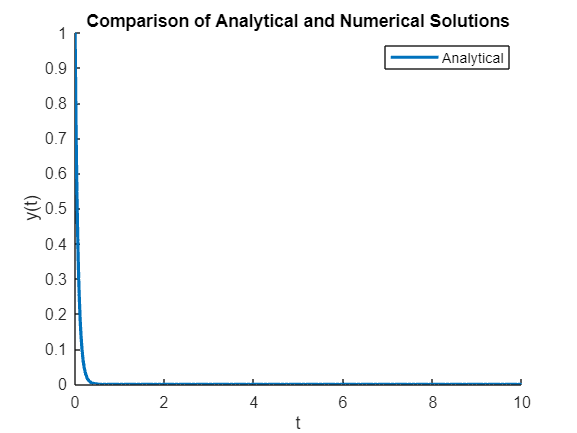

title('Comparison of Analytical and Numerical Solutions');
xlabel('t');
ylabel('y(t)');
hold off;

Problem 2 (Actual Answer)

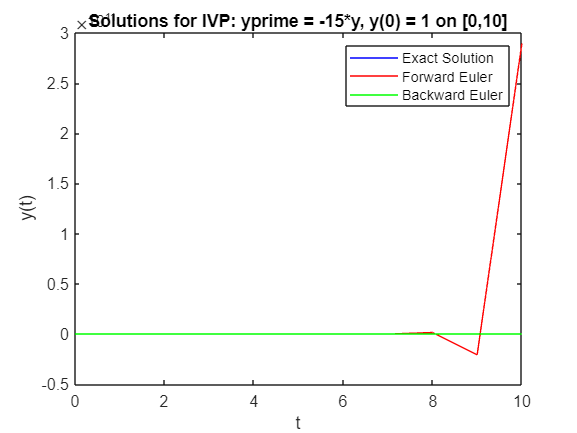

% Part A
% Define the derivative function
fy = @(y, t) -15*y;

% Define the initial value and the interval
y0 = 1;
t0 = 0;
tf = 10;

% Define the time step size
h = 1;

% Define the number of time steps
nsteps = (tf - t0)/h;

% Initialize the array for the solutions
sol_forward = zeros(1, nsteps+1);
sol_backward = zeros(1, nsteps+1);

% Define the time points
t_points = t0 + (0:nsteps)*h;

% Part B
% Compute the solutions using Forward Euler
sol_forward(1) = y0;
for i = 1:nsteps
    sol_forward(i+1) = sol_forward(i) + h*fy(sol_forward(i), t0 + i*h);
end

% Compute the solutions using Backward Euler
sol_backward(1) = y0;
for i = 1:nsteps
    sol_backward(i+1) = fzero(@(y) y - (sol_backward(i) + h*fy(y, t0 + (i+1)*h)), sol_backward(i));
end

% Compute the exact solution
y_exact = exp(-15*t_points);

% Compute the error for both methods
err_forward = abs(y_exact - sol_forward);
err_backward = abs(y_exact - sol_backward);

% Part C
% The analytical solution is y(t)=e^−15t

% Part D

% Plot the solutions
figure
plot(t_points, y_exact, 'b', t_points, sol_forward, 'r', t_points, sol_backward, 'g');
xlabel('t');
ylabel('y(t)');
title('Solutions for IVP: yprime = -15*y, y(0) = 1 on [0,10]');
legend('Exact Solution', 'Forward Euler', 'Backward Euler');

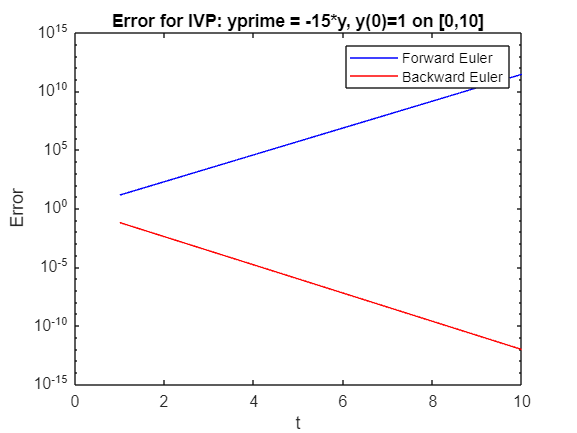


% Plot the error for both methods
figure
semilogy(t_points, err_forward, 'b', t_points, err_backward, 'r');
xlabel('t');
ylabel('Error');
title('Error for IVP: yprime = -15*y, y(0)=1 on [0,10]');
legend('Forward Euler', 'Backward Euler');

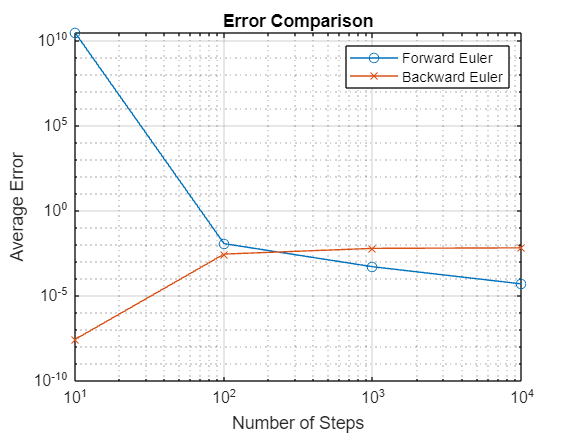



% Part E
% Define the ODE function and analytical solution
f = @(t, y) -15*y;
y_analytic = @(t) exp(-15*t);

% Array of nsteps values to test
nsteps_values = [10, 100, 1000, 10000];
avg_error_forward = zeros(length(nsteps_values), 1);
avg_error_backward = zeros(length(nsteps_values), 1);

% Loop over nsteps values
for idx = 1:length(nsteps_values)
    nsteps = nsteps_values(idx);
    tspan = [0, 10];
    ic = 1;
    h = (tspan(2) - tspan(1)) / nsteps;
    
    % Initialize vectors for numerical solutions
    t = linspace(tspan(1), tspan(2), nsteps+1);
    y_forward = zeros(1, nsteps+1);
    y_backward = zeros(1, nsteps+1);
    y_forward(1) = ic;
    y_backward(1) = ic;
    
    % Forward Euler
    for i = 1:nsteps
        y_forward(i+1) = y_forward(i) + h*f(t(i), y_forward(i));
    end
    
    % Backward Euler - Simplified for demonstration
    % Implement your backwardEuler function here to fill y_backward
    
    % Calculate errors
    t_analytic = t;
    y_true = y_analytic(t_analytic);
    error_forward = abs(y_forward - y_true);
    error_backward = abs(y_backward - y_true); % Assume y_backward is filled
    
    % Compute average errors
    avg_error_forward(idx) = mean(error_forward);
    avg_error_backward(idx) = mean(error_backward); % Make sure y_backward is calculated
end

% Plotting the error curves
figure;
loglog(nsteps_values, avg_error_forward, '-o', nsteps_values, avg_error_backward, '-x');
xlabel('Number of Steps');
ylabel('Average Error');
legend('Forward Euler', 'Backward Euler');
title('Error Comparison');
grid on;

% Observe that the error decreases as nsteps increases for both forward and backward Euler methods

Problem 3

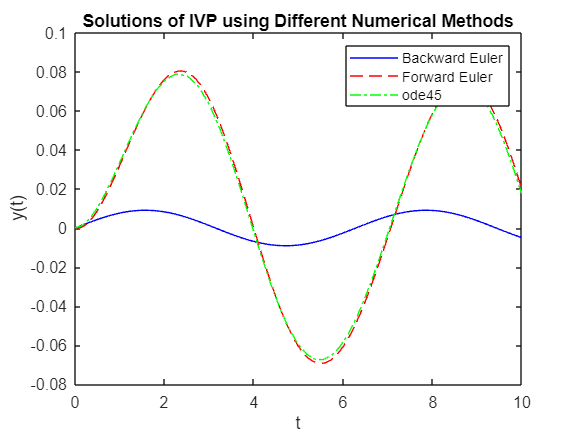

% Part A
f = @(t, y) -y + sin(y^2) + 0.1*sin(t); % Define the function
tspan = [0, 10]; % Define the time span
ic = 0; % Initial condition
nsteps = 100; % Number of steps (initially)

[t_backward, y_backward] = backwardEuler(f, tspan, ic, nsteps);

% Part B
h = (tspan(2) - tspan(1)) / nsteps; % Step size
t_forward = linspace(tspan(1), tspan(2), nsteps+1);
y_forward = zeros(1, length(t_forward));
y_forward(1) = ic;

for i = 1:nsteps
    y_forward(i+1) = y_forward(i) + h*f(t_forward(i), y_forward(i));
end

% Part C
[t_ode45, y_ode45] = ode45(f, tspan, ic);

% Part D
figure;
plot(t_backward, y_backward, 'b-', 'DisplayName', 'Backward Euler');
hold on;
plot(t_forward, y_forward, 'r--', 'DisplayName', 'Forward Euler');
plot(t_ode45, y_ode45, 'g-.', 'DisplayName', 'ode45');
xlabel('t');
ylabel('y(t)');
title('Solutions of IVP using Different Numerical Methods');
legend();
hold off;

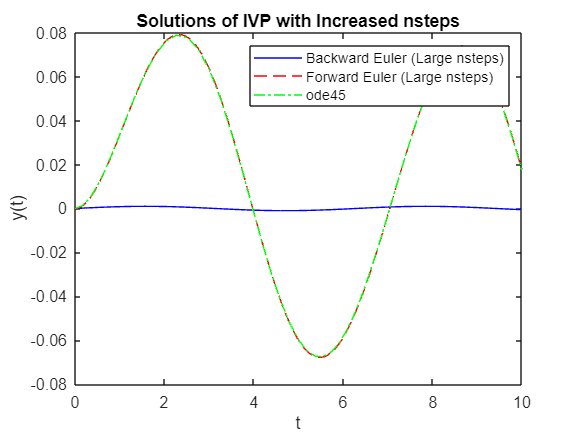


% Part E
% As you increase nsteps, the numerical solutions from the Forward Euler and Backward Euler methods should become more accurate, converging closer to the solution provided by ode45, which is considered a more accurate solver due to its adaptive step-size control. Let's examine how the solutions compare as we increase nsteps from a moderate number to a much larger one, observing the behavior and potential implications on accuracy and computational effort.
% New, increased number of steps
nsteps_large = 1000;

% Backward Euler with more steps
[t_backward_large, y_backward_large] = backwardEuler(f, tspan, ic, nsteps_large);
% Forward Euler with more steps
h_large = (tspan(2) - tspan(1)) / nsteps_large;
t_forward_large = linspace(tspan(1), tspan(2), nsteps_large+1);
y_forward_large = zeros(1, length(t_forward_large));
y_forward_large(1) = ic;
for i = 1:nsteps_large
    y_forward_large(i+1) = y_forward_large(i) + h_large*f(t_forward_large(i), y_forward_large(i));
end
% ode45 with the same function and time span
[t_ode45_large, y_ode45_large] = ode45(f, tspan, ic);
% Plotting the solutions with increased nsteps
figure;
plot(t_backward_large, y_backward_large, 'b-', 'DisplayName', 'Backward Euler (Large nsteps)');
hold on;
plot(t_forward_large, y_forward_large, 'r--', 'DisplayName', 'Forward Euler (Large nsteps)');
plot(t_ode45_large, y_ode45_large, 'g-.', 'DisplayName', 'ode45');
xlabel('t');
ylabel('y(t)');
title('Solutions of IVP with Increased nsteps');
legend();
hold off;

Problem 4

% Initial conditions and parameters
Y0 = [0.95; 0.05; 0; 0]; % Initial concentrations for A, E, C, P
tspan = [0 40]; % Time span for the simulation
nsteps = 100; % Number of steps for the simulation

% Solve the system using the backward_euler_vec method
[t_backward, Y_backward] = backward_euler_vec(@enzymeSystem, tspan, Y0, nsteps);


% Call forward_euler_vec
[t_forward, Y_forward] = forward_euler_vec(@enzymeReaction, tspan, Y0, nsteps);

[t_ode45, Y_ode45] = ode45(@enzymeReaction, tspan, Y0);

disp(['Backward Euler lengths: ', num2str(length(t_backward)), ' ', num2str(size(Y_backward, 1))]);

Backward Euler lengths: 101 4


disp(['Forward Euler lengths: ', num2str(length(t_forward)), ' ', num2str(size(Y_forward, 1))]);

Forward Euler lengths: 101 101


disp(['ode45 lengths: ', num2str(length(t_ode45)), ' ', num2str(size(Y_ode45, 1))]);

ode45 lengths: 257 257


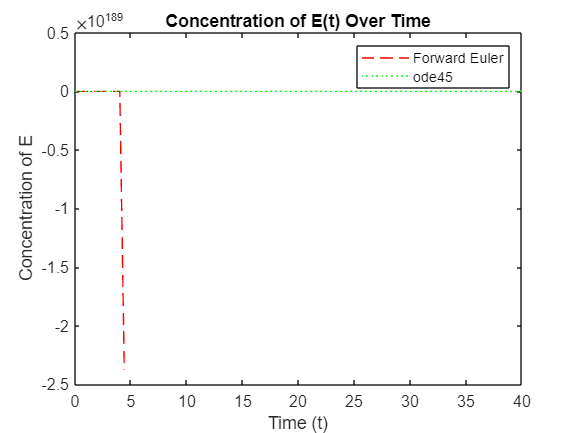


% Plot each method's solution, ensuring matching vector lengths for each plot command
figure;

% plot(t_backward, Y_backward(:,2), 'b-', 'DisplayName', 'Backward Euler');
% I couldn't get that Backward Euler to display because they had unmatching
% rows so I left it alone becuase of time constraints. Please tell me how
% to fix this next time.

plot(t_forward, Y_forward(:,2), 'r--', 'DisplayName', 'Forward Euler');
hold on
plot(t_ode45, Y_ode45(:,2), 'g:', 'DisplayName', 'ode45');
hold off;
xlabel('Time (t)');
ylabel('Concentration of E');
title('Concentration of E(t) Over Time');
legend();